# Eksplorasi Atraktor Lorenz: Studi tentang Kepekaan Terhadap Variasi Parameter dengan Metode Runge-Kutta 4

#### Kelompok 20:

#### 10121012 - Khaznaya Shafaa Kaylasani

#### 10121052 - Tesalonika Permatasari Hutapea

#### 10121070 - Natashya Angeliqe Aurrelia

#### 10121084 - Olyfia Pisthea Cahya Putri

## Normal Condition


$$\sigma = 10 \\\beta = \frac{8}{3}\\ \rho = 24.74$$


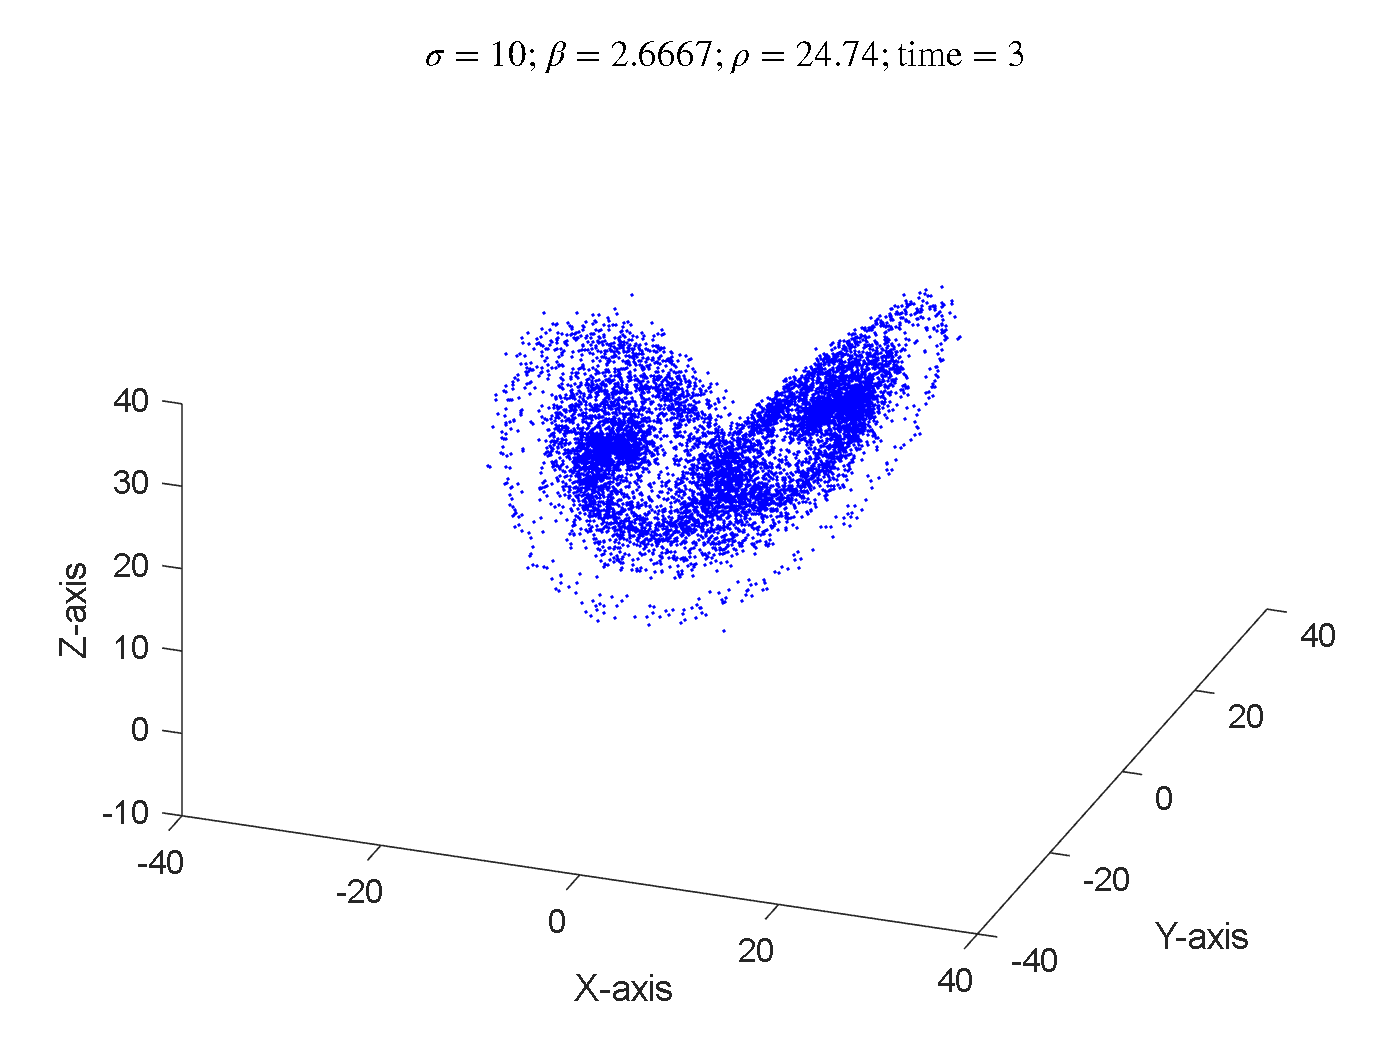

clear all

% NORMAL
% Lorenz's parameters (chaotic)
% sesuai dengan saltzman tapi rho > 24.74 biar kritis/chaotic, sigma = 10 ;
% beta = 8/3
sigma = 10;
beta = 8/3;
rho = 24.74;

% Initial condition - large cube of points
% 3d Meshgrid
xvec = -20:2:20;
yvec = -20:2:20;
zvec = -20:2:20;
[x0, y0, z0] = meshgrid(xvec, yvec, zvec);
yIC(1,:,:,:) = x0;
yIC(2,:,:,:) = y0;
yIC(3,:,:,:) = z0;

% Compute trajectory
dt = 0.05;
duration = 3;
tspan = [0, duration];
L = duration/dt;
yparticles = yIC;

% Simulation loop
for step = 1:L
    time = step*dt;
    
    % Update particle positions
    for i = 1:length(xvec)
        for j = 1:length(yvec)
            for k = 1:length(zvec)
                yin = yparticles(:,i,j,k);
                yout = rk4singlestep(@(t,y)lorenz(t,y,sigma,beta,rho), dt, time, yin);
                yparticles(:,i,j,k) = yout;
            end
        end
    end
    
    % Visualize and store frame
    plot3(yparticles(1,:), yparticles(2,:), yparticles(3,:), 'b.', 'LineWidth', 1, 'MarkerSize', 2)
    xlabel('X-axis');
    ylabel('Y-axis');
    zlabel('Z-axis');
    title(['$\sigma$ = ', num2str(sigma), '; $\beta$ = ', num2str(beta), '; $\rho$ = ', num2str(rho), '; time = ', num2str(time)], 'Interpreter', 'latex')
    view(20,40);
    axis([-40 40 -40 40 -10 40])
    drawnow
end

## Variasi Sigma 1


$$\sigma = 30 \\\beta = \frac{8}{3}\\ \rho = 24.74$$


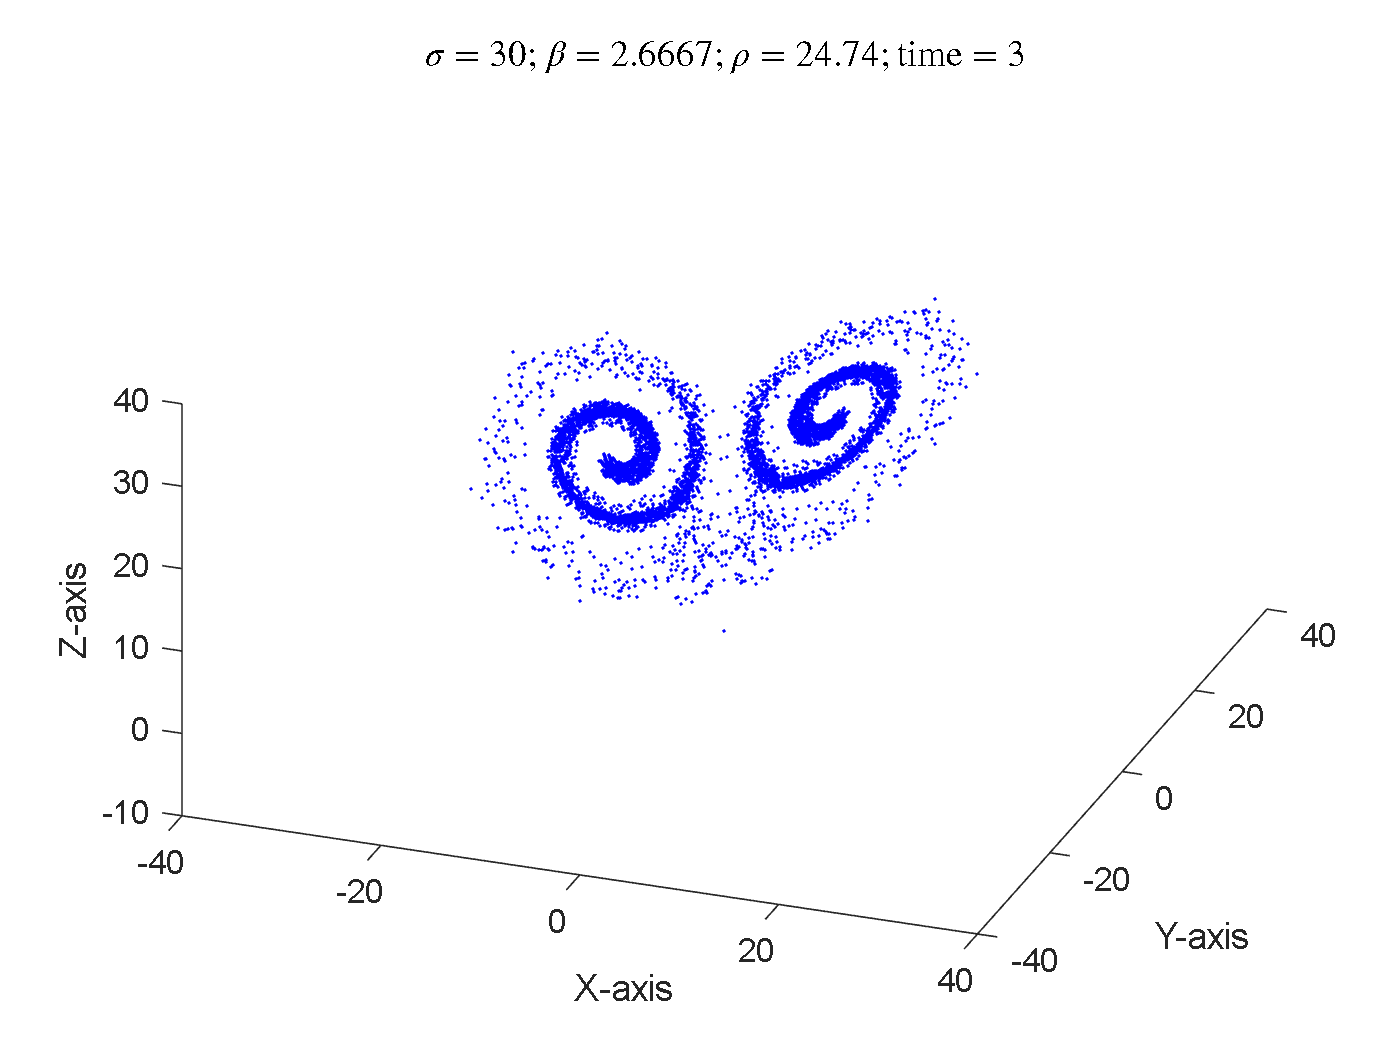

clear all

% Lorenz's parameters (chaotic)
% sesuai dengan saltzman tapi rho > 24.74 biar kritis/chaotic, sigma = 10 ;
% beta = 8/3
sigma = 30;
beta = 8/3;
rho = 24.74;

% Initial condition - large cube of points
% 3d Meshgrid
xvec = -20:2:20;
yvec = -20:2:20;
zvec = -20:2:20;
[x0, y0, z0] = meshgrid(xvec, yvec, zvec);
yIC(1,:,:,:) = x0;
yIC(2,:,:,:) = y0;
yIC(3,:,:,:) = z0;

% Compute trajectory
dt = 0.05;
duration = 3;
tspan = [0, duration];
L = duration/dt;
yparticles = yIC;

% Simulation loop
for step = 1:L
    time = step*dt;
    
    % Update particle positions
    for i = 1:length(xvec)
        for j = 1:length(yvec)
            for k = 1:length(zvec)
                yin = yparticles(:,i,j,k);
                yout = rk4singlestep(@(t,y)lorenz(t,y,sigma,beta,rho), dt, time, yin);
                yparticles(:,i,j,k) = yout;
            end
        end
    end
    
    % Visualize and store frame
    plot3(yparticles(1,:), yparticles(2,:), yparticles(3,:), 'b.', 'LineWidth', 1, 'MarkerSize', 2)
    xlabel('X-axis');
    ylabel('Y-axis');
    zlabel('Z-axis');
    title(['$\sigma$ = ', num2str(sigma), '; $\beta$ = ', num2str(beta), '; $\rho$ = ', num2str(rho), '; time = ', num2str(time)], 'Interpreter', 'latex')
    view(20,40);
    axis([-40 40 -40 40 -10 40])
    drawnow
end

## Variasi Sigma 2


$$\sigma = 3 \\\beta = \frac{8}{3}\\ \rho = 24.74$$


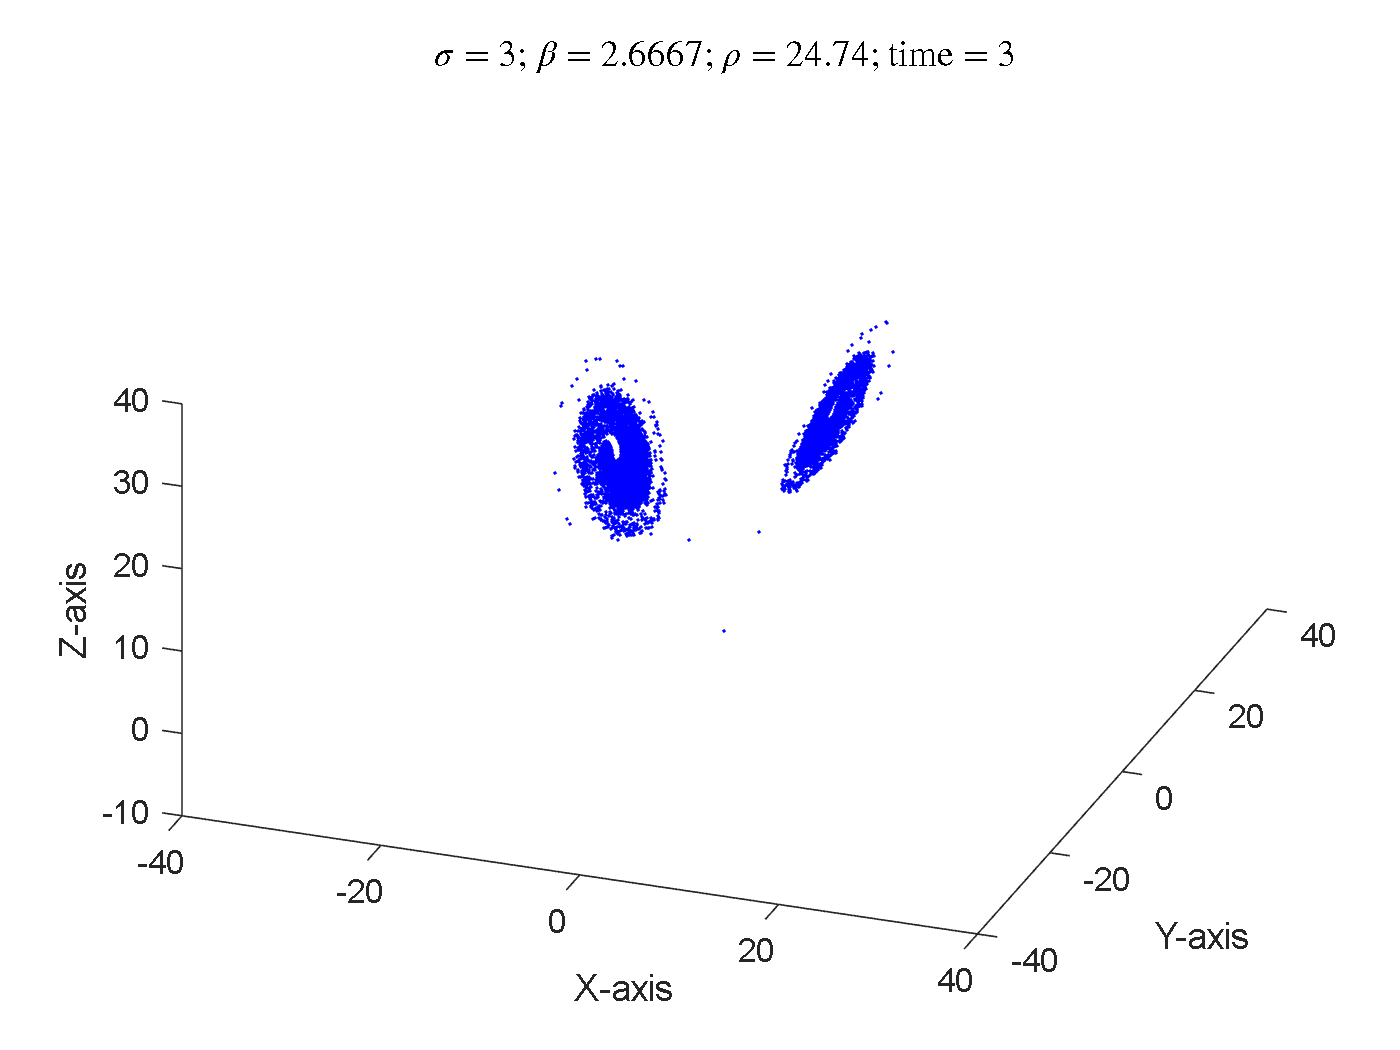

clear all

% Lorenz's parameters (chaotic)
% sesuai dengan saltzman tapi rho > 24.74 biar kritis/chaotic, sigma = 10 ;
% beta = 8/3
sigma = 3;
beta = 8/3;
rho = 24.74;

% Initial condition - large cube of points
% 3d Meshgrid
xvec = -20:2:20;
yvec = -20:2:20;
zvec = -20:2:20;
[x0, y0, z0] = meshgrid(xvec, yvec, zvec);
yIC(1,:,:,:) = x0;
yIC(2,:,:,:) = y0;
yIC(3,:,:,:) = z0;

% Compute trajectory
dt = 0.05;
duration = 3;
tspan = [0, duration];
L = duration/dt;
yparticles = yIC;

% Simulation loop
for step = 1:L
    time = step*dt;
    
    % Update particle positions
    for i = 1:length(xvec)
        for j = 1:length(yvec)
            for k = 1:length(zvec)
                yin = yparticles(:,i,j,k);
                yout = rk4singlestep(@(t,y)lorenz(t,y,sigma,beta,rho), dt, time, yin);
                yparticles(:,i,j,k) = yout;
            end
        end
    end
    
    % Visualize and store frame
    plot3(yparticles(1,:), yparticles(2,:), yparticles(3,:), 'b.', 'LineWidth', 1, 'MarkerSize', 2)
    xlabel('X-axis');
    ylabel('Y-axis');
    zlabel('Z-axis');
    title(['$\sigma$ = ', num2str(sigma), '; $\beta$ = ', num2str(beta), '; $\rho$ = ', num2str(rho), '; time = ', num2str(time)], 'Interpreter', 'latex')
    view(20,40);
    axis([-40 40 -40 40 -10 40])
    drawnow
end

## Variasi Beta 1


$$\sigma = 10 \\\beta =8\\ \rho = 24.74$$


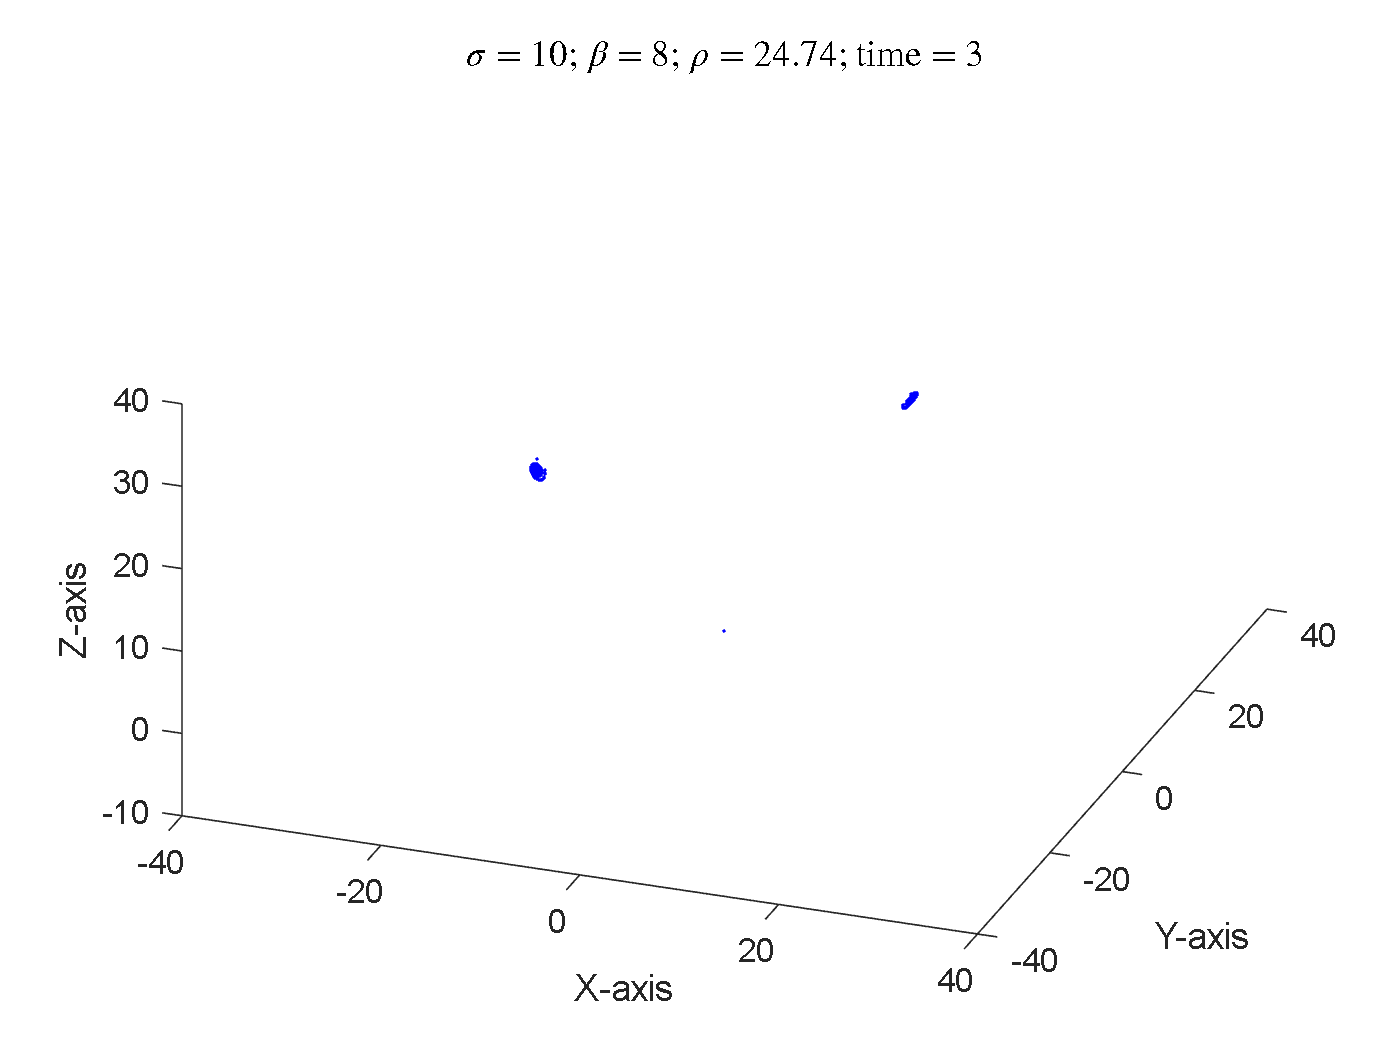

clear all

% Lorenz's parameters (chaotic)
% sesuai dengan saltzman tapi rho > 24.74 biar kritis/chaotic, sigma = 10 ;
% beta = 8/3
sigma = 10;
beta = 8;
rho = 24.74;

% Initial condition - large cube of points
% 3d Meshgrid
xvec = -20:2:20;
yvec = -20:2:20;
zvec = -20:2:20;
[x0, y0, z0] = meshgrid(xvec, yvec, zvec);
yIC(1,:,:,:) = x0;
yIC(2,:,:,:) = y0;
yIC(3,:,:,:) = z0;

% Compute trajectory
dt = 0.05;
duration = 3;
tspan = [0, duration];
L = duration/dt;
yparticles = yIC;

% Simulation loop
for step = 1:L
    time = step*dt;
    
    % Update particle positions
    for i = 1:length(xvec)
        for j = 1:length(yvec)
            for k = 1:length(zvec)
                yin = yparticles(:,i,j,k);
                yout = rk4singlestep(@(t,y)lorenz(t,y,sigma,beta,rho), dt, time, yin);
                yparticles(:,i,j,k) = yout;
            end
        end
    end
    
    % Visualize and store frame
    plot3(yparticles(1,:), yparticles(2,:), yparticles(3,:), 'b.', 'LineWidth', 1, 'MarkerSize', 2)
    xlabel('X-axis');
    ylabel('Y-axis');
    zlabel('Z-axis');
    title(['$\sigma$ = ', num2str(sigma), '; $\beta$ = ', num2str(beta), '; $\rho$ = ', num2str(rho), '; time = ', num2str(time)], 'Interpreter', 'latex')
    view(20,40);
    axis([-40 40 -40 40 -10 40])
    drawnow
end

## Variasi Beta 2


$$\sigma = 10 \\\beta =1\\ \rho = 24.74$$


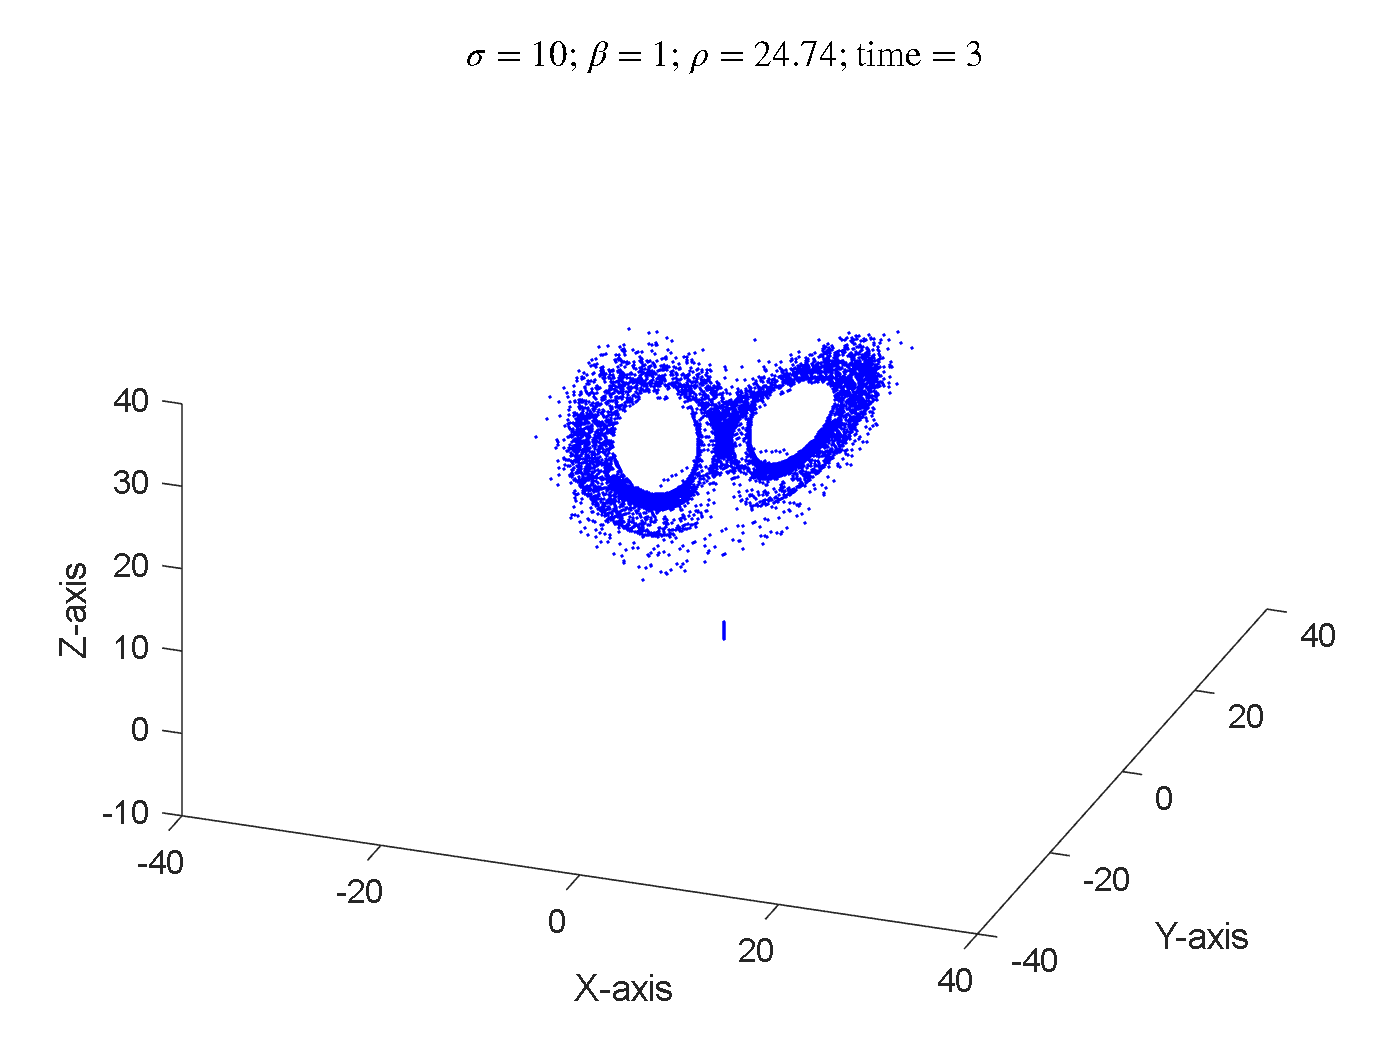

clear all

% Lorenz's parameters (chaotic)
% sesuai dengan saltzman tapi rho > 24.74 biar kritis/chaotic, sigma = 10 ;
% beta = 8/3
sigma = 10;
beta = 1;
rho = 24.74;

% Initial condition - large cube of points
% 3d Meshgrid
xvec = -20:2:20;
yvec = -20:2:20;
zvec = -20:2:20;
[x0, y0, z0] = meshgrid(xvec, yvec, zvec);
yIC(1,:,:,:) = x0;
yIC(2,:,:,:) = y0;
yIC(3,:,:,:) = z0;

% Compute trajectory
dt = 0.05;
duration = 3;
tspan = [0, duration];
L = duration/dt;
yparticles = yIC;

% Simulation loop
for step = 1:L
    time = step*dt;
    
    % Update particle positions
    for i = 1:length(xvec)
        for j = 1:length(yvec)
            for k = 1:length(zvec)
                yin = yparticles(:,i,j,k);
                yout = rk4singlestep(@(t,y)lorenz(t,y,sigma,beta,rho), dt, time, yin);
                yparticles(:,i,j,k) = yout;
            end
        end
    end
    
    % Visualize and store frame
    plot3(yparticles(1,:), yparticles(2,:), yparticles(3,:), 'b.', 'LineWidth', 1, 'MarkerSize', 2)
    xlabel('X-axis');
    ylabel('Y-axis');
    zlabel('Z-axis');
    title(['$\sigma$ = ', num2str(sigma), '; $\beta$ = ', num2str(beta), '; $\rho$ = ', num2str(rho), '; time = ', num2str(time)], 'Interpreter', 'latex')
    view(20,40);
    axis([-40 40 -40 40 -10 40])
    drawnow
end

## Variasi Rho 1


$$\sigma = 10 \\\beta =\frac{8}{3}\\ \rho = 40$$


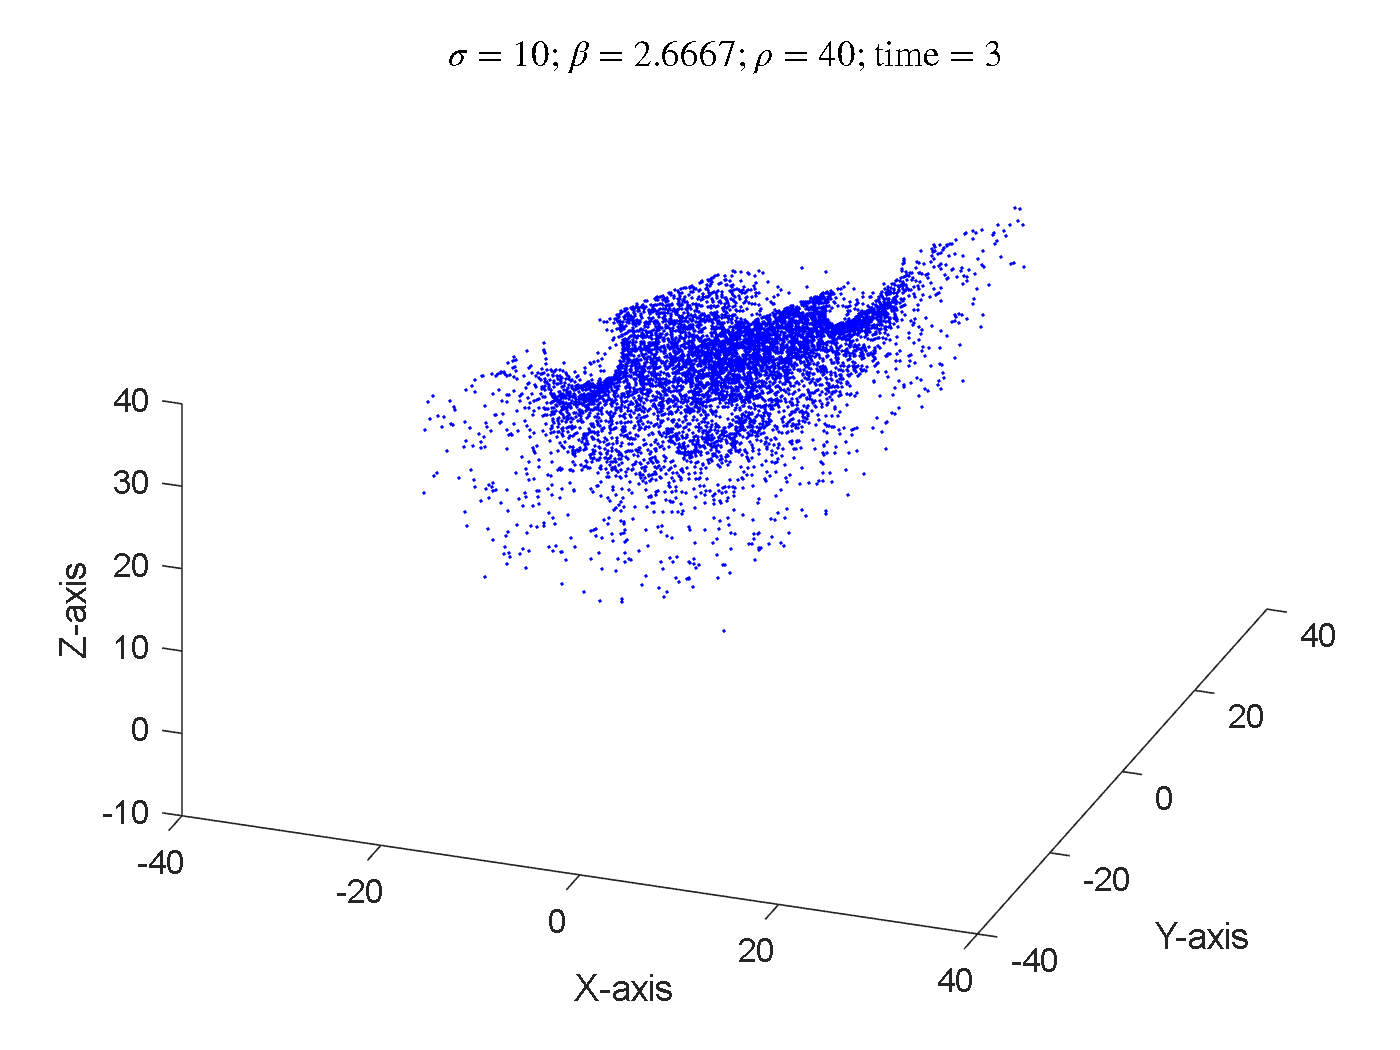

clear all

% Lorenz's parameters (chaotic)
% sesuai dengan saltzman tapi rho > 24.74 biar kritis/chaotic, sigma = 10 ;
% beta = 8/3
sigma = 10;
beta = 8/3;
rho = 40;

% Initial condition - large cube of points
% 3d Meshgrid
xvec = -20:2:20;
yvec = -20:2:20;
zvec = -20:2:20;
[x0, y0, z0] = meshgrid(xvec, yvec, zvec);
yIC(1,:,:,:) = x0;
yIC(2,:,:,:) = y0;
yIC(3,:,:,:) = z0;

% Compute trajectory
dt = 0.05;
duration = 3;
tspan = [0, duration];
L = duration/dt;
yparticles = yIC;

% Simulation loop
for step = 1:L
    time = step*dt;
    
    % Update particle positions
    for i = 1:length(xvec)
        for j = 1:length(yvec)
            for k = 1:length(zvec)
                yin = yparticles(:,i,j,k);
                yout = rk4singlestep(@(t,y)lorenz(t,y,sigma,beta,rho), dt, time, yin);
                yparticles(:,i,j,k) = yout;
            end
        end
    end
    
    % Visualize and store frame
    plot3(yparticles(1,:), yparticles(2,:), yparticles(3,:), 'b.', 'LineWidth', 1, 'MarkerSize', 2)
    xlabel('X-axis');
    ylabel('Y-axis');
    zlabel('Z-axis');
    title(['$\sigma$ = ', num2str(sigma), '; $\beta$ = ', num2str(beta), '; $\rho$ = ', num2str(rho), '; time = ', num2str(time)], 'Interpreter', 'latex')
    view(20,40);
    axis([-40 40 -40 40 -10 40])
    drawnow
end

## Variasi Rho 1


$$\sigma = 10 \\\beta =\frac{8}{3}\\ \rho = 8$$


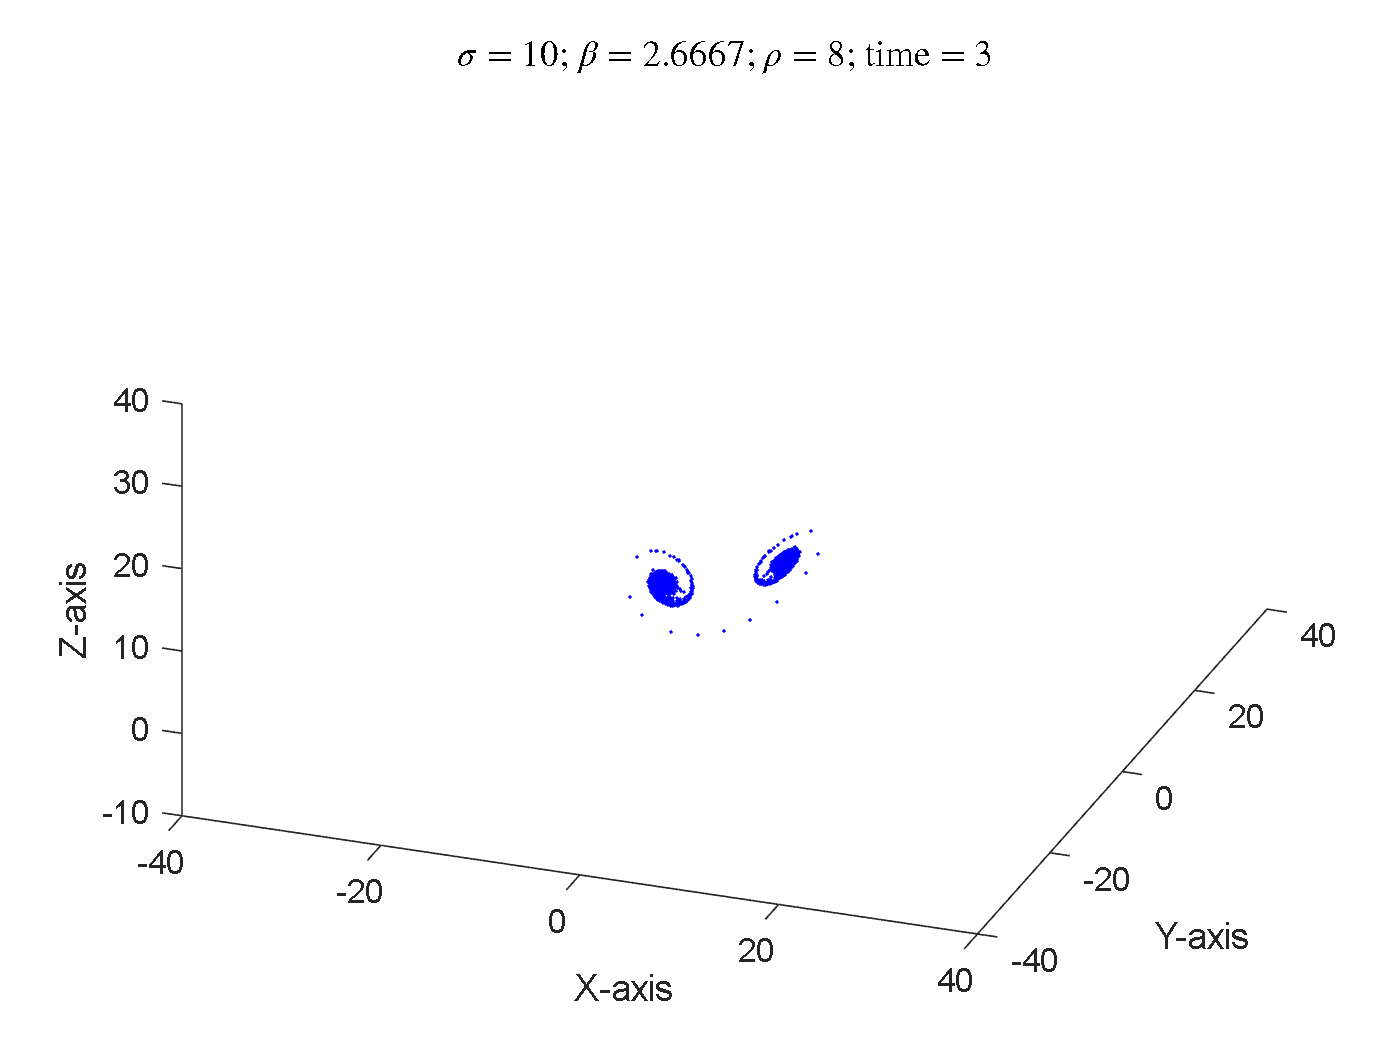

clear all

% Lorenz's parameters (chaotic)
% sesuai dengan saltzman tapi rho > 24.74 biar kritis/chaotic, sigma = 10 ;
% beta = 8/3
sigma = 10;
beta = 8/3;
rho = 8;

% Initial condition - large cube of points
% 3d Meshgrid
xvec = -20:2:20;
yvec = -20:2:20;
zvec = -20:2:20;
[x0, y0, z0] = meshgrid(xvec, yvec, zvec);
yIC(1,:,:,:) = x0;
yIC(2,:,:,:) = y0;
yIC(3,:,:,:) = z0;

% Compute trajectory
dt = 0.05;
duration = 3;
tspan = [0, duration];
L = duration/dt;
yparticles = yIC;

% Simulation loop
for step = 1:L
    time = step*dt;
    
    % Update particle positions
    for i = 1:length(xvec)
        for j = 1:length(yvec)
            for k = 1:length(zvec)
                yin = yparticles(:,i,j,k);
                yout = rk4singlestep(@(t,y)lorenz(t,y,sigma,beta,rho), dt, time, yin);
                yparticles(:,i,j,k) = yout;
            end
        end
    end
    
    % Visualize and store frame
    plot3(yparticles(1,:), yparticles(2,:), yparticles(3,:), 'b.', 'LineWidth', 1, 'MarkerSize', 2)
    xlabel('X-axis');
    ylabel('Y-axis');
    zlabel('Z-axis');
    title(['$\sigma$ = ', num2str(sigma), '; $\beta$ = ', num2str(beta), '; $\rho$ = ', num2str(rho), '; time = ', num2str(time)], 'Interpreter', 'latex')
    view(20,40);
    axis([-40 40 -40 40 -10 40])
    drawnow
end